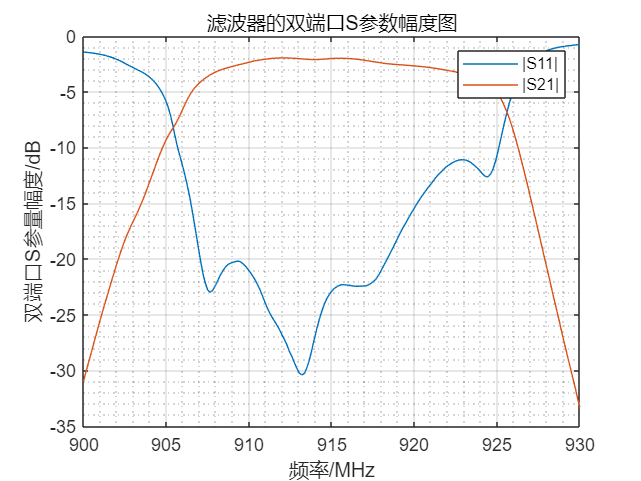

clear;clc;
load LPF.mat;
load 3DB.mat;
load CAS2.mat;
f=LPF(:,1);
S11=LPF(:,2)+1i*LPF(:,3);
S21=LPF(:,4)+1i*LPF(:,5);
S12=LPF(:,6)+1i*LPF(:,7);
S22=LPF(:,8)+1i*LPF(:,9);

S_3db=DB(:,2)+1i*DB(:,3);
S_cas=CAS2(:,2)+1i*CAS2(:,3);
phi_meas=get_phi(S_cas);

gamma_Zl=S_3db;
gamma_cal=S11+S12.*S12.*gamma_Zl./(1-S22.*gamma_Zl);
phi_cal=get_phi(gamma_cal);

figure();
plot(f/1000000,20*log10(abs(S11)));
hold on;
plot(f/1000000,20*log10(abs(S21)));
grid on;grid minor;
legend('|S11|','|S21|');
title('滤波器的双端口S参数幅度图');
xlabel('频率/MHz');
ylabel('双端口S参量幅度/dB');

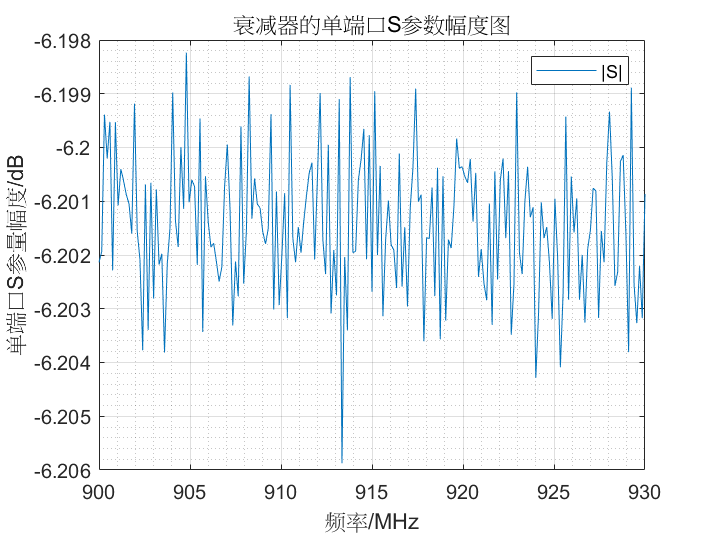


figure();
plot(f/1000000,20*log10(abs(S_3db)));
grid on;grid minor;
legend('|S|');
title('衰减器的单端口S参数幅度图');
xlabel('频率/MHz');
ylabel('单端口S参量幅度/dB');

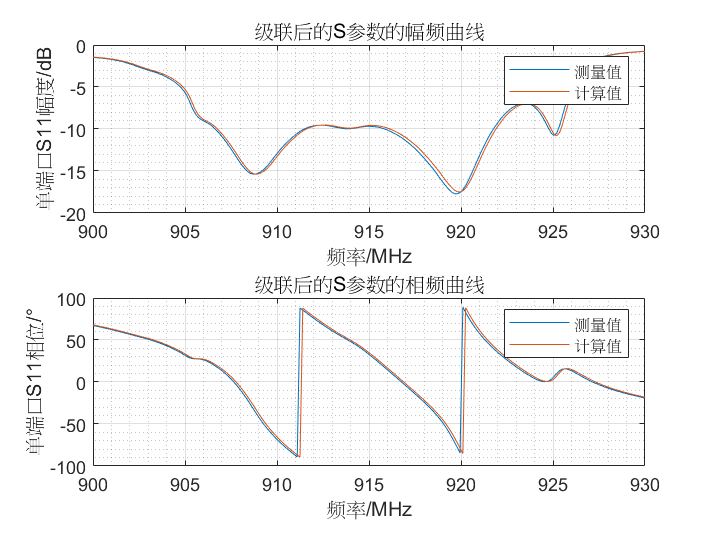



figure();
subplot(2,1,1);
plot(f/1000000,20*log10(abs(S_cas)));%测量值
hold on;
plot(f/1000000,20*log10(abs(gamma_cal)));%计算值
grid on;grid minor;
legend('测量值','计算值');
title('级联后的S参数的幅频曲线');
xlabel('频率/MHz');
ylabel('单端口S11幅度/dB');

subplot(2,1,2);
plot(f/1000000,phi_meas);%测量值
hold on;
plot(f/1000000,phi_cal);%计算值
grid on;grid minor;
legend('测量值','计算值');
title('级联后的S参数的相频曲线');
xlabel('频率/MHz');
ylabel('单端口S11相位/°');

function phi=get_phi(S)
    S_abs=abs(S);
    phi_e=S./S_abs;
    phi=-1i.* log(phi_e) ;
    phi=real(phi.*(180/2/pi));
end